clear
close all

[y,Fs] = audioread("Count Bubbas Revenge_short.wav");
y = y(:,1)

y =     0.0000
   -0.0001
    0.0001
   -0.0001
    0.0001
   -0.0001
    0.0001
   -0.0000
    0.0000
   -0.0000


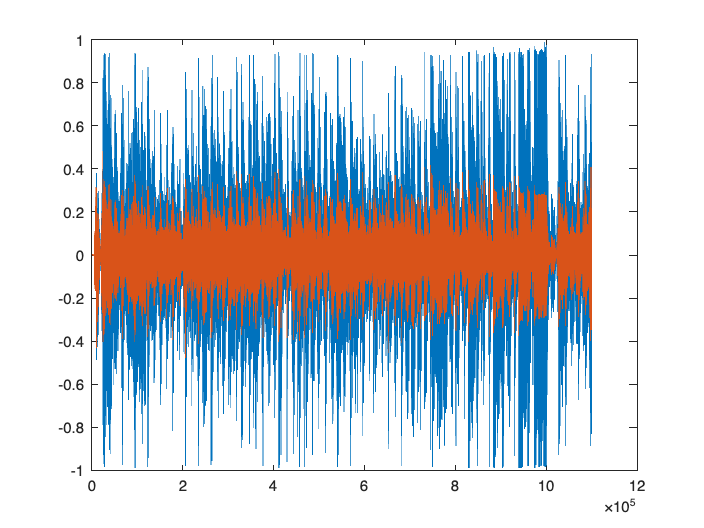

plot(y)
hold on;

AttackTime = 0.02; %% seconds
ReleaseTime = 2; %% seconds
Threshold = -16; %%dB
Ratio = 4;
TC = log(9.0);

AT = exp(-TC/(AttackTime * Fs));
RT = exp(-TC/(ReleaseTime * Fs));

env_prev = 0;

for n = 1:length(y)

    rect = y(n) * y(n);

    if rect > env_prev
        alpha = AT;
    else
        alpha = RT;
    end

    e(n) = (1 - alpha) * (rect) + alpha * env_prev;

    env_prev = e(n);

    d(n) = 20*log10(sqrt(e(n)));

    if e(n) == 0
        d(n) = -96;
    end

    if d(n) <= Threshold
        g(n) = 0;
    else
        g(n) = Threshold + (d(n) - Threshold)/Ratio - d(n);
    end

    y(n) = y(n) * db2mag(g(n));

end

plot(y)

%%plot(Rtd)
%%soundsc(y,Fs)


